clc;
clear;
load('example_data.mat');
load('SegmentationValues.mat');
load("SingleFeatures.mat");
springer_options.audio_Fs = 1000;

%As the data for Anomalies is arranged as S1 Systole
%S2 and Diastole and repeats the same sequence the
%Signals stored in Diastole, Systole, S1, S2 need to be
%Augmented to fit such sequence

Dummy = 0;
for i = 1:numel(Diastole)
        
        Sounds_RegionsS1          = S1{i};
        Sounds_Regions(Dummy + 1) = {Sounds_RegionsS1};

        Sounds_RegionsSystole     = Systole{i};
        Sounds_Regions(Dummy + 2) = {Sounds_RegionsSystole};

        Sounds_RegionsS2          = S2{i};
        Sounds_Regions(Dummy + 3) = {Sounds_RegionsS2};

        Sounds_RegionsDiastole    = Diastole{i};
        Sounds_Regions(Dummy + 4) = {Sounds_RegionsDiastole};

        Dummy = Dummy + 4;
end

%Turning Anomalies numeric values 0 1 to normal and abnormal for easier
%interpretation
Anomalies_S = cell(1, length(Anomalies));

% Logical indexing to replace 0 with 'normal' and 1 with 'abnormal'
Anomalies_S(Anomalies == 0) = {'normal'};
Anomalies_S(Anomalies == 1) = {'abnormal'};
Anomalies_C = categorical(Anomalies_S);
labels = Anomalies_C;

%Creating a signal datastore
sigds = signalDatastore(Sounds_Regions);

%Split the data set into three sets for training, validation, and testing
idx = splitlabels(labels,[0.8 0.1]);
traindata = Sounds_Regions(idx{1});
traindata = traindata'; %Transposing for the correct input dimension
trainlabels = labels(idx{1});
valdata = Sounds_Regions(idx{2});
valdata = valdata';
vallabels = labels(idx{2});
testdata = Sounds_Regions(idx{3});
testdata = testdata';
testlabels = labels(idx{3});

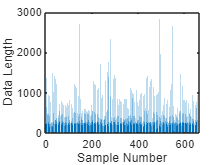

sequenceLengths = cellfun(@length,Sounds_Regions);
bar(sequenceLengths)
ylabel("Data Length")
xlabel("Sample Number")

%Train Network
layers = [
    sequenceInputLayer(1,"Name","input")
    lstmLayer(128,"Name","lstm","OutputMode","last")
    dropoutLayer(0.5,"Name","dropout")
    fullyConnectedLayer(2,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classification")];

opts = trainingOptions("adam", ...
    "ValidationData",{valdata vallabels}, ...
    "Plots","training-progress","InitialLearnRate",0.01, ...
    "MaxEpochs",30, "SequenceLength",1500, "L2Regularization", 0.001);

%L2Regularization prevents overfitting by adding a penalty term to the loss function
%this penalty term discourages the model from assigning too much importance to any one feature or parameter, 
%thereby reducing the model's complexity and improving its ability to generalize to new data

anomalynet = trainNetwork(traindata,trainlabels,layers,opts)

% testpred = classify(anomalynet,testdata)
% msk = signalMask(testlabels ~= testpred)
% plotsigroi(msk,testdata,true)